MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

MAIN_DIR = "C:\Users\gridd\OneDrive\Рабочий стол\ITMO\fourier_labs\Lab6\image\"

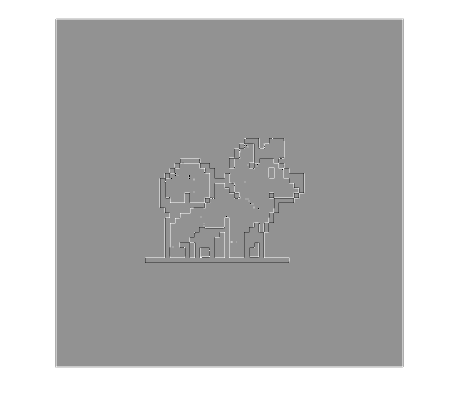

img = im2gray(imread(MAIN_DIR + "5.jpg"));
img = img / 255;
kernel = [-1, -1, -1;-1, 8, -1;-1, -1, -1];
img_kernel_conv2 = conv2(img, kernel);
maxi1 = max(img_kernel_conv2(:));
mini1 = min(img_kernel_conv2(:));
img_kernel_conv2 = (img_kernel_conv2 - mini1) / (maxi1 - mini1);
imshow(img_kernel_conv2);

img_kernel_conv_pad = conv_pad(img, kernel);
mini2 = min(img_kernel_conv_pad(:))

mini2 = -8.0000

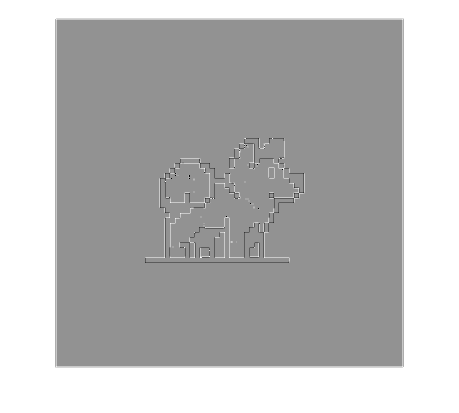

maxi2 = max(img_kernel_conv_pad(:));
img_kernel_conv_pad = (img_kernel_conv_pad - mini2)/(maxi2 - mini2);
imshow(img_kernel_conv_pad);

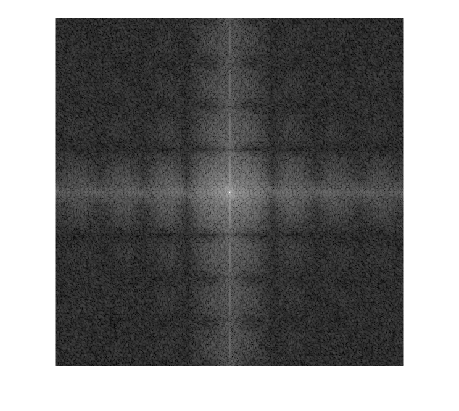



image_fourier = fftshift(fft2(img));  % calc Fourier transform on image

module = log(1+abs(image_fourier)); 
module = (module-min(module(:)))/(max(module(:))-min(module(:)));
imshow(module);

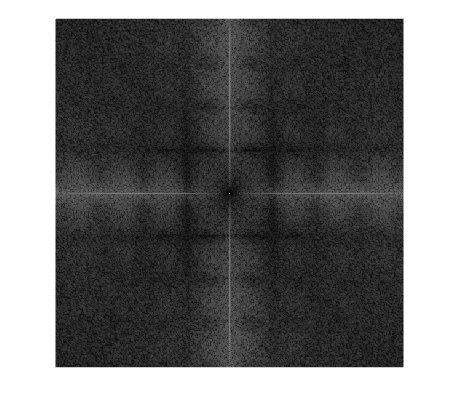

imwrite(module, MAIN_DIR + "test_module_fourier_image.jpg");
cont_image_fourier=fftshift(fft2(img_kernel_conv_pad));
cont_module = log(1 + abs(cont_image_fourier));
cont_module = (cont_module - min(cont_module(:)))/(max(cont_module(:)) - min(cont_module(:)));
imshow(cont_module);

imwrite(cont_module, MAIN_DIR + "test_cont_module.jpeg");


function y = conv_pad(img, kernel)
    h = height(img);
    w = width(img);
    fourier_transform_img = fftshift(fft2(img, h+height(kernel)-1,w+width(kernel)-1));
    fourier_transform_kernel = fftshift(fft2(kernel, h+height(kernel)-1,w+width(kernel)-1)); 
    fft_conv = fourier_transform_img.*fourier_transform_kernel;
    y = ifft2(ifftshift(fft_conv));
end